t = tiledlayout(1, 3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


dir = readtable("PtDirectorySimple.xlsx")

dir = 9×9 table
    Patient    Hemisphere            JsonSurvey                     JsonStream             StartIndex    DoubleBattery        maxBetaChan             maxThetaChan            maxGammaChan    
    _______    __________    ___________________________    ___________________________    __________    _____________    ____________________    ____________________    ____________________

       1       {'LEFT' }     {'pt1_0524_l_survey.json' }    {'pt1_0524_l_stream.json' }        7               1          {'ZERO_THREE_LEFT' }    {'ZERO_THREE_LEFT' }    {'ZERO_TWO_LEFT'   }
       1       {'RIGHT'}     {'pt1_0524_r_survey.json' }    {'pt1_0524_r_stream.json' }        7        

alldat = []; 
pt = {}; 
chan = {}; 
info = table;  
for i = 1:height(dir)
    jsonFiles = dir.JsonSurvey{i};
    side = dir.Hemisphere{i};
    startIndex = dir.StartIndex(i);
    num = num2str(dir.Patient(i));
    hemi = upper(dir.Hemisphere(i));

    js = jsondecode(fileread(jsonFiles));
    outTABLE = extractSurveyData(js, side, startIndex);
    chans = unique(outTABLE.ChanID, 'stable');
    %beta 12-33, 86 data points
    %theta 5-9 17 data points
    %gamma 60-90, 123 data points
    for k = 1:length(chans)
        c = (chans{k});
        chanNameParts = split(c,'_');
        c = join(chanNameParts(1:3),'_');
        oneChan = oneChanStats(outTABLE, c, 12, 33, 0.25);

        pttab = repmat({['pt', num, hemi{1}]}, 9,1);
        chantab = repmat({c}, 9, 1);
        %sets up which runs to take out
        runs = {'Run1', 'Run2'; 'Run1', 'Run3'; 'Run2', 'Run3'};
        %chop oneChan into the 3 groups of 2 and run using this
        pt = [pt; pttab];
        chan = [chan; chantab];

        for j = 1:3
            %grab index if it matches the above row of the groups
            temprun = ismember(oneChan.Identifiers, runs(j, :)) ;
            %grabs data from oneChan based upon if it has the right groups
            tempdata = oneChan(temprun, :);
            %feed the groups to dabest
            outputdata = dabest_sl(tempdata);
            %if the lower limit is negative and the upper limit is positive
            %basically find if the region contains zero
            issig = 0 > outputdata.CIs(3,1) & 0 < outputdata.CIs(3,2);
            %containing zero is a non-sig difference so switch the logical value
            issig = ~issig;
            sig = [0; 0; issig];
            %add the data to the general output data
            outputdata = addvars(outputdata, (sig), 'NewVariableNames', 'Sig');
            alldat = [alldat; outputdata];

            close all
        end
    end
end

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3




%add pt and freq info 
alldat.Patients = pt;
alldat.Chan = chan; 
freq = repmat({'beta'}, 486, 1);
alldat.Freq = freq; 
writetable(alldat, 'betataballcontact.xlsx')  

sigrunbeta = []; 
%locate the rows with signficant differences and save them 
for k = 1:height(alldat) 
    if alldat.Sig(k) == 1 
        sigrunbeta = [sigrunbeta; alldat(k, :)]; 
    end
end  

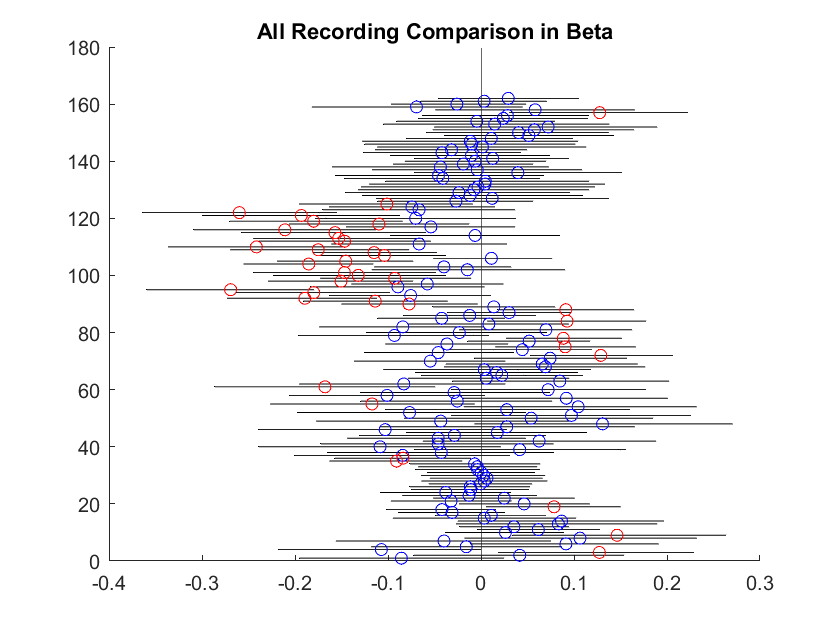


data = readtable("betataballcontact.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

close all 
y = [1:height(data2); 1:height(data2)]; 
x = transpose([data2.CIs_1, data2.CIs_2]);
line(x,y, 'color', 'k', 'LineWidth', 0.5)
hold on 
y2 = (1:height(data2)); 
y3 = (1:height(data3)); 
plot(data2.Value, y2, 'bo', 'MarkerFaceColor', "none")
plot(data3.Value, indicies, 'ro')
xline(0) 
title("All Recording Comparison in Beta")

%change colors and thickness in order to show the ones that are dissimilar 
%add theta and gamma 
%find better data that is contact agnostic  

dir = readtable("PtDirectorySimple.xlsx")

dir = 9×9 table
    Patient    Hemisphere            JsonSurvey                     JsonStream             StartIndex    DoubleBattery        maxBetaChan             maxThetaChan            maxGammaChan    
    _______    __________    ___________________________    ___________________________    __________    _____________    ____________________    ____________________    ____________________

       1       {'LEFT' }     {'pt1_0524_l_survey.json' }    {'pt1_0524_l_stream.json' }        7               1          {'ZERO_THREE_LEFT' }    {'ZERO_THREE_LEFT' }    {'ZERO_TWO_LEFT'   }
       1       {'RIGHT'}     {'pt1_0524_r_survey.json' }    {'pt1_0524_r_stream.json' }        7        

alldat = []; 
pt = {}; 
chan = {}; 
info = table;  
for i = 1:height(dir)
    jsonFiles = dir.JsonSurvey{i};
    side = dir.Hemisphere{i};
    startIndex = dir.StartIndex(i);
    num = num2str(dir.Patient(i));
    hemi = upper(dir.Hemisphere(i));

    js = jsondecode(fileread(jsonFiles));
    outTABLE = extractSurveyData(js, side, startIndex);
    chans = unique(outTABLE.ChanID, 'stable');
    %beta 12-33, 86 data points
    %theta 5-9 17 data points
    %gamma 60-90, 123 data points
    for k = 1:length(chans)
        c = (chans{k});
        chanNameParts = split(c,'_');
        c = join(chanNameParts(1:3),'_');
        oneChan = oneChanStats(outTABLE, c, 4, 8, 0.25);

        pttab = repmat({['pt', num, hemi{1}]}, 9,1);
        chantab = repmat({c}, 9, 1);
        %sets up which runs to take out
        runs = {'Run1', 'Run2'; 'Run1', 'Run3'; 'Run2', 'Run3'};
        %chop oneChan into the 3 groups of 2 and run using this
        pt = [pt; pttab];
        chan = [chan; chantab];

        for j = 1:3
            %grab index if it matches the above row of the groups
            temprun = ismember(oneChan.Identifiers, runs(j, :)) ;
            %grabs data from oneChan based upon if it has the right groups
            tempdata = oneChan(temprun, :);
            %feed the groups to dabest
            outputdata = dabest_sl(tempdata);
            %if the lower limit is negative and the upper limit is positive
            %basically find if the region contains zero
            issig = 0 > outputdata.CIs(3,1) & 0 < outputdata.CIs(3,2);
            %containing zero is a non-sig difference so switch the logical value
            issig = ~issig;
            sig = [0; 0; issig];
            %add the data to the general output data
            outputdata = addvars(outputdata, (sig), 'NewVariableNames', 'Sig');
            alldat = [alldat; outputdata];

            close all
        end
    end
end

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3




%add pt and freq info 
alldat.Patients = pt;
alldat.Chan = chan; 
freq = repmat({'theta'}, 486, 1);
alldat.Freq = freq; 
writetable(alldat, 'thetataballcontact.xlsx')  

sigrunbeta = []; 
%locate the rows with signficant differences and save them 
for k = 1:height(alldat) 
    if alldat.Sig(k) == 1 
        sigrunbeta = [sigrunbeta; alldat(k, :)]; 
    end
end  

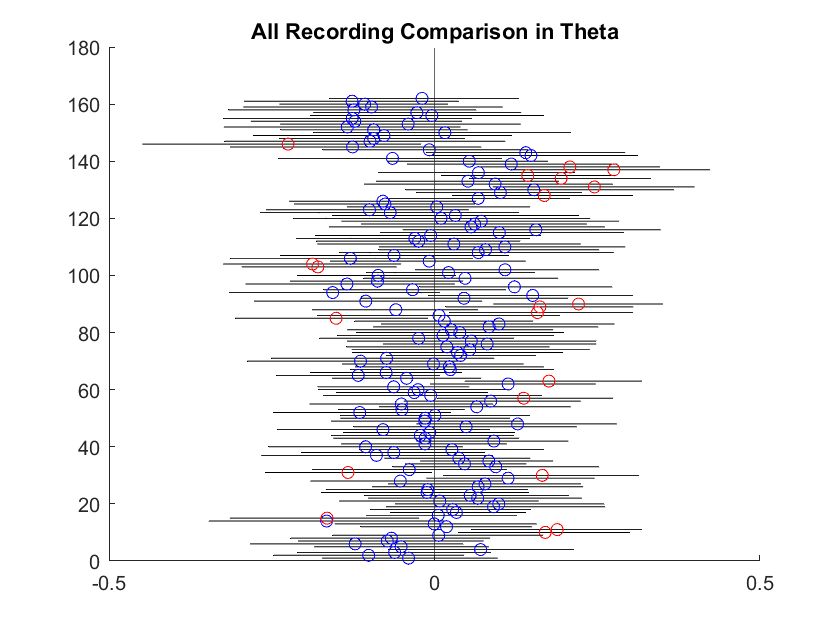

g = 2; 
s1 = subplot(3,1,g); 
s1.FontSize = 10; 
data = readtable("thetataballcontact.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

close all 
y = [1:height(data2); 1:height(data2)]; 
x = transpose([data2.CIs_1, data2.CIs_2]);
line(x,y, 'color', 'k', 'LineWidth', 0.5)
hold on 
y2 = (1:height(data2)); 
y3 = (1:height(data3)); 
plot(data2.Value, y2, 'bo', 'MarkerFaceColor', "none")
plot(data3.Value, indicies, 'ro')
xline(0) 
title("All Recording Comparison in Theta")

dir = readtable("PtDirectorySimple.xlsx")

dir = 9×9 table
    Patient    Hemisphere            JsonSurvey                     JsonStream             StartIndex    DoubleBattery        maxBetaChan             maxThetaChan            maxGammaChan    
    _______    __________    ___________________________    ___________________________    __________    _____________    ____________________    ____________________    ____________________

       1       {'LEFT' }     {'pt1_0524_l_survey.json' }    {'pt1_0524_l_stream.json' }        7               1          {'ZERO_THREE_LEFT' }    {'ZERO_THREE_LEFT' }    {'ZERO_TWO_LEFT'   }
       1       {'RIGHT'}     {'pt1_0524_r_survey.json' }    {'pt1_0524_r_stream.json' }        7        

alldat = []; 
pt = {}; 
chan = {}; 
info = table;  
for i = 1:height(dir)
    jsonFiles = dir.JsonSurvey{i};
    side = dir.Hemisphere{i};
    startIndex = dir.StartIndex(i);
    num = num2str(dir.Patient(i));
    hemi = upper(dir.Hemisphere(i));

    js = jsondecode(fileread(jsonFiles));
    outTABLE = extractSurveyData(js, side, startIndex);
    chans = unique(outTABLE.ChanID, 'stable');
    %beta 12-33, 86 data points
    %theta 5-9 17 data points
    %gamma 60-90, 123 data points
    for k = 1:length(chans)
        c = (chans{k});
        chanNameParts = split(c,'_');
        c = join(chanNameParts(1:3),'_');
        oneChan = oneChanStats(outTABLE, c, 34, 100, 0.25);

        pttab = repmat({['pt', num, hemi{1}]}, 9,1);
        chantab = repmat({c}, 9, 1);
        %sets up which runs to take out
        runs = {'Run1', 'Run2'; 'Run1', 'Run3'; 'Run2', 'Run3'};
        %chop oneChan into the 3 groups of 2 and run using this
        pt = [pt; pttab];
        chan = [chan; chantab];

        for j = 1:3
            %grab index if it matches the above row of the groups
            temprun = ismember(oneChan.Identifiers, runs(j, :)) ;
            %grabs data from oneChan based upon if it has the right groups
            tempdata = oneChan(temprun, :);
            %feed the groups to dabest
            outputdata = dabest_sl(tempdata);
            %if the lower limit is negative and the upper limit is positive
            %basically find if the region contains zero
            issig = 0 > outputdata.CIs(3,1) & 0 < outputdata.CIs(3,2);
            %containing zero is a non-sig difference so switch the logical value
            issig = ~issig;
            sig = [0; 0; issig];
            %add the data to the general output data
            outputdata = addvars(outputdata, (sig), 'NewVariableNames', 'Sig');
            alldat = [alldat; outputdata];

            close all
        end
    end
end

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3

     1     2     3




%add pt and freq info 
alldat.Patients = pt;
alldat.Chan = chan; 
freq = repmat({'gamma'}, 486, 1);
alldat.Freq = freq; 
writetable(alldat, 'gammataballcontact.xlsx')  

sigrunbeta = []; 
%locate the rows with signficant differences and save them 
for k = 1:height(alldat) 
    if alldat.Sig(k) == 1 
        sigrunbeta = [sigrunbeta; alldat(k, :)]; 
    end
end  

g = 3; 

g = 3

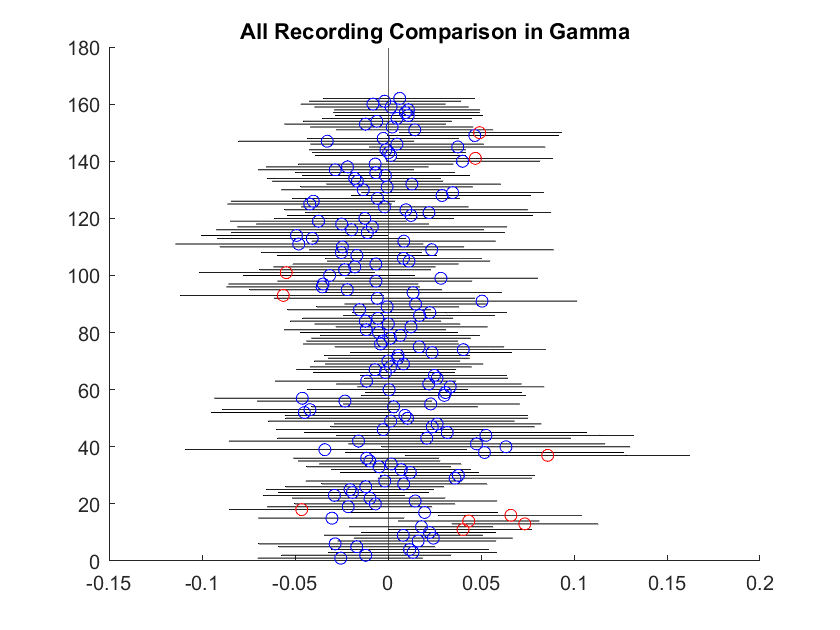

s1 = subplot(3,1,g); 
s1.FontSize = 10; 
data = readtable("gammataballcontact.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

close all 
y = [1:height(data2); 1:height(data2)]; 
x = transpose([data2.CIs_1, data2.CIs_2]);
line(x,y, 'color', 'k', 'LineWidth', 0.5)
hold on 
y2 = (1:height(data2)); 
y3 = (1:height(data3)); 
plot(data2.Value, y2, 'bo', 'MarkerFaceColor', "none")
plot(data3.Value, indicies, 'ro')
xline(0) 
title("All Recording Comparison in Gamma")